clear all


## Define contour of the doc

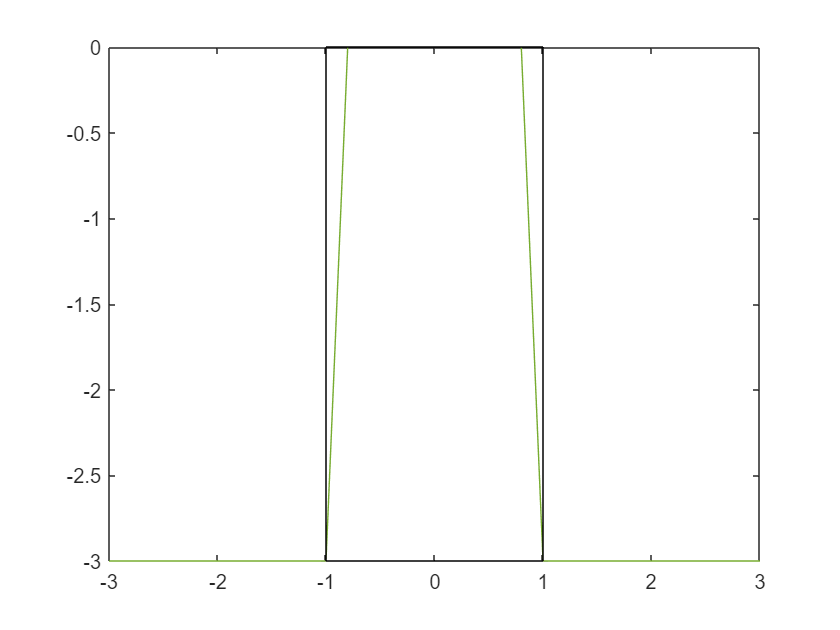

 

d = 3; %depth [m]
w = 1; %width [m] 
w_toll = 0.9; 
s = 10e-3; %sharpness

sig = @(x)1/(1+exp(-x)); %sigmoid function

x_plot= -3:0.1:3;
f = zeros(1, length(x_plot)); 

for i =1:length(x_plot)
   
    f(i, :) = -d + d*(sig((x_plot(i)+w_toll)/s) - sig((x_plot(i)-w_toll)/s)); 
end

plot(x_plot, f); hold on; 

% Define the position, width, and height of the rectangle
width = w;
hight= d;
x_doc = -width;
y_doc = -d; 


% Draw the rectangle
rectangle('Position', [x_doc y_doc width*2 hight]);
hold off; 

We see in the lower corners the allowed area is 0.1 m to large. In the upper corners the allowed area is 0.1 m to little. This is with s = 10e-3

## Plot h~(extremal points)

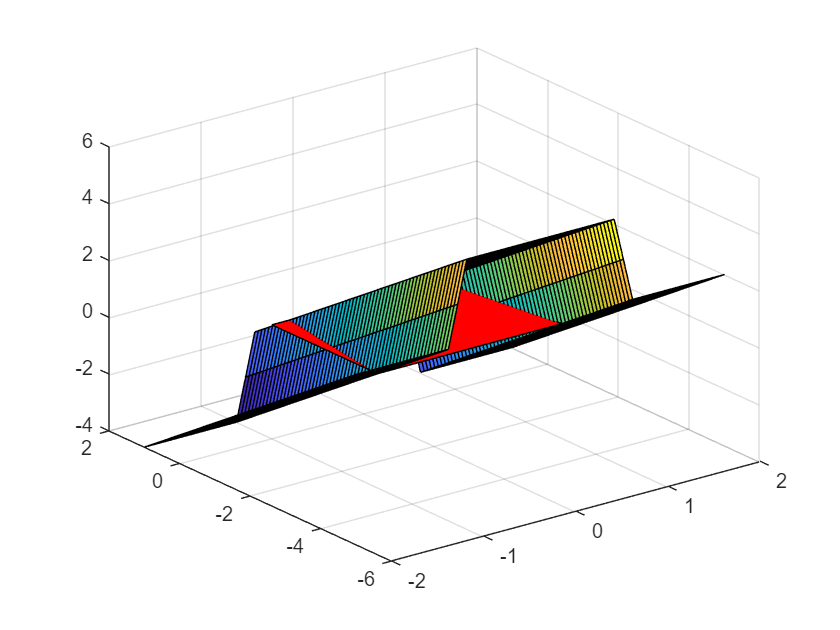



x_test = -2:0.1:2; 
y_test = -5:0.1:1; 

[X, Y] = meshgrid(x_test, y_test); 

doc =@(x) -d + d*(sig((x+w_toll)/s) - sig((x-w_toll)/s)); 

DOC = zeros(size(X)); 

for r = 1:size(X, 1)
    for c = 1:size(X,2)
        DOC(r, c) = doc(X(r,c)); 
    end
end

Z = DOC - Y; 

surf(X,Y,Z)

hold on

rect_x = [x_doc, x_doc, x_doc + width*2, x_doc + width*2]; 
rect_y = [y_doc, y_doc + hight, y_doc + hight, y_doc]; 
rect_z = [1, 1, 1, 1]*(0);

patch(rect_x, rect_y, rect_z, 'r')